Aqui se realizaran las pruebas para los metodos de encontrar raices 

cosas a arreglar

- eliminar la variable global sol1 de todos los metodos

- la numeracion en cada matriz de resultados esta mal

- el metodo de punto fijo no funciona

- documentar todas las funciones

f = @(x) x.^3-cos(x)

f = function_handle with value:
    @(x)x.^3-cos(x)


fsym = sym(f)

$$fsym = x^{3}-\cos\left(x\right)$$





resultados = newtonraphson(10,10,0.001,fsym)

resultados =                    0   6.657809020070726                   0
   1.000000000000000   4.451608628403299   2.206200391667426
   2.000000000000000   2.938816211824450   1.512792416578849
   3.000000000000000   1.929253339126085   1.009562872698365
   4.000000000000000   1.306939799637985   0.622313539488100
   5.000000000000000   0.983183567974778   0.323756231663207
   6.000000000000000   0.877075423658100   0.106108144316678
   7.000000000000000   0.865602682568395   0.011472741089706
   8.000000000000000   0.865474049165541   0.000128633402853


sol1 = resultados(end,2)

sol1 =    0.865474049165541


x1=[0,numel(resultados(:,1))-1]

x1 =      0     8


y1=[sol1,sol1]

y1 =    0.865474049165541   0.865474049165541


x2=sol1(1)-0.75*abs(sol1(1)):0.01:sol1(1)+0.75*abs(sol1(1))

x2 =    0.216368512291385   0.226368512291385   0.236368512291385   0.246368512291385   0.256368512291385   0.266368512291385   0.276368512291385   0.286368512291385   0.296368512291385   0.306368512291385   0.316368512291385   0.326368512291385   0.336368512291385   0.346368512291385   0.356368512291385   0.366368512291385   0.376368512291385   0.386368512291385   0.396368512291385   0.406368512291385   0.416368512291385   0.426368512291385   0.436368512291385   0.446368512291385   0.456368512291385   0.466368512291385   0.476368512291385   0.486368512291385   0.496368512291385   0.506368512291385   0.516368512291385   0.526368512291385   0.536368512291385   0.546368512291385   0.556368512291386   0.566368512291386   0.576368512291385   0.586368512291385   0.596368512291385   0.606368512291385   0.616368512291385   0.626368512291385   0.636368512291385   0.646368512291385   0.656368512291385   0.666368512291385   0.676368512291385   0.686368512291385   0.696368512291385   0.7063685122

y2=double(subs(fsym,symvar(fsym),x2))

y2 =   -0.966554146889138  -0.962888136030988  -0.958988856090477  -0.954850536374525  -0.950467415911834  -0.945833743428991  -0.940943777325593  -0.935791785648408  -0.930372046064572  -0.924678845833819  -0.918706481779757  -0.912449260260188  -0.905901497136470  -0.899057517741930  -0.891911656849336  -0.884458258637413  -0.876691676656433  -0.868606273792852  -0.860196422233030  -0.851456503426006  -0.842380908045357  -0.832964035950131  -0.823200296144859  -0.813084106738657  -0.802609894903416  -0.791772096831082  -0.780565157690040  -0.768983531580597  -0.757021681489571  -0.744674079243997  -0.731935205463936  -0.718799549514424  -0.705261609456528  -0.691315891997544  -0.676956912440324  -0.662179194631750  -0.646977270910348  -0.631345682053051  -0.615278977221129  -0.598771713905267  -0.581818457869818  -0.564413783096231  -0.546552271725646  -0.528228514000687  -0.509437108206435  -0.490172660610601  -0.470429785402900  -0.450203104633629  -0.429487248151470  -0.4082768535

hold on
plot(x2,y2)
sol2 = vpasolve(fsym,symvar(fsym)),double(subs(fsym,symvar(fsym),vpasolve(fsym,symvar(fsym))))

$$sol2 = 0.86547403310161444662068590118623$$

ans =      0


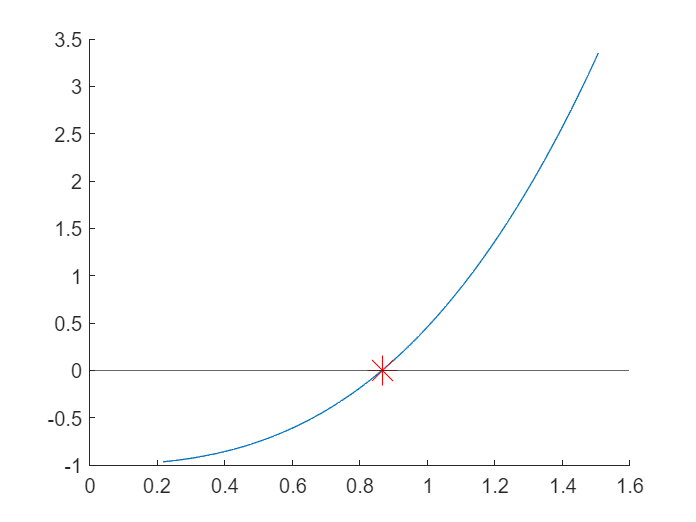

plot(sol2,0,"Color",'r',"Marker","*","MarkerSize",15)
xline(0)
yline(0)

hold off

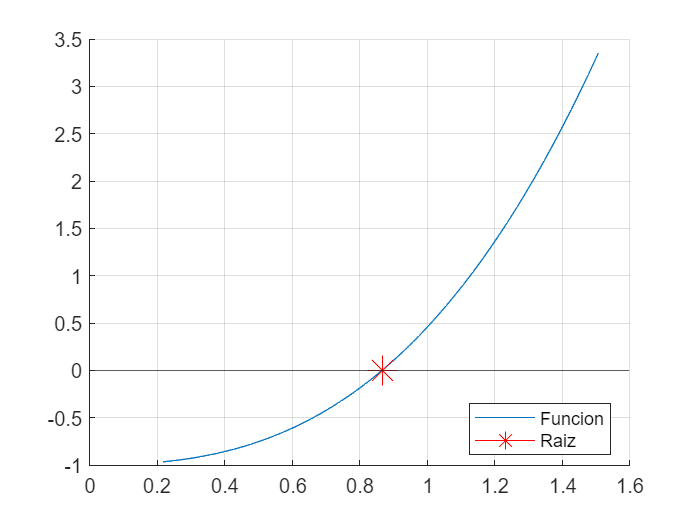

ans =                    0                   0                   0
   1.000000000000000   0.500000000000000   0.500000000000000
   2.000000000000000   0.750000000000000   0.250000000000000
   3.000000000000000   0.875000000000000   0.125000000000000
   4.000000000000000   0.812500000000000   0.062500000000000
   5.000000000000000   0.843750000000000   0.031250000000000
   6.000000000000000   0.859375000000000   0.015625000000000
   7.000000000000000   0.867187500000000   0.007812500000000
   8.000000000000000   0.863281250000000   0.003906250000000
   9.000000000000000   0.865234375000000   0.001953125000000


biseccion(-1,1,10,0.001,fsym)